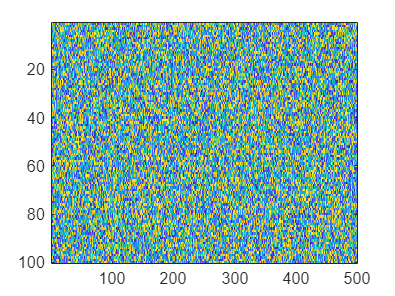

% Generate random data
data = randi([0, 100], 10, 5);
data1 = randi([0, 255], 100, 500);

% Write data to .csv file
writematrix(data, 'random_data.csv')

% Write data to .png file
imagesc(data1)
saveas(gcf,'random_data.png')


% Write data to excel file
writematrix(data, 'random_data.xlsx', 'Sheet', 1)

% Write data to .txt file using 'writematrix' 
writematrix(data,'random_data.txt')

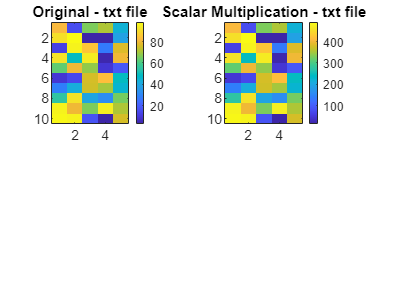

% Load .txt file
data_txt = load('random_data.txt');
% Scalar multiplication
new_data_txt = data_txt .* 5;
% Dot product
dot_prod_txt = dot(data_txt(:,1), data_txt(:,2));
% Triangle matrix
L_txt = tril(data_txt);
% Identity matrix
I_txt = eye(size(data_txt));

% Plot original file
subplot(221)
imagesc(data_txt)
title('Original - txt file')
colorbar
% Plot result file
subplot(222)
imagesc(new_data_txt)
title('Scalar Multiplication - txt file')
colorbar

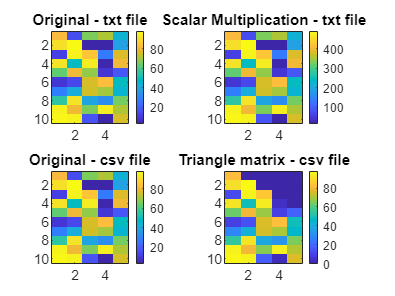

% Load .csv file
data_csv = readmatrix('random_data.csv');
% Scalar multiplication
new_data_csv = data_csv .* 10;
% Dot product
dot_prod_csv = dot(data_csv(:,1), data_csv(:,2));
% Triangle matrix
L_csv = tril(data_csv);
% Identity matrix
I_csv = eye(size(data_csv));

% Plot original file
subplot(223)
imagesc(data_csv)
title('Original - csv file')
colorbar
% Plot result file
subplot(224)
imagesc(L_csv)
title('Triangle matrix - csv file')
colorbar

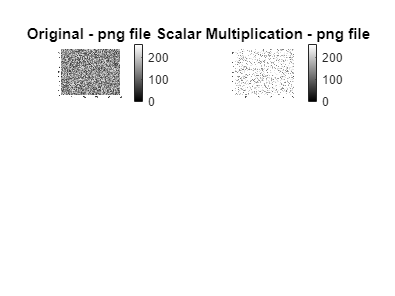

% Load .png file as grayscale
data_png = imread('random_data.png');
data_png = rgb2gray(data_png);
% Scalar multiplication
new_data_png = data_png .* 2;
% Dot product
%dot_prod_png = dot(data_png(:,1), data_png(:,2));
% Triangle matrix
L_png = tril(double(data_png));
% Identity matrix
I_png = eye(size(data_png));

% Plot original file
figure
subplot(221)
imshow(data_png)
title('Original - png file')
colorbar
% Plot result file
subplot(222)
imshow(new_data_png)
title('Scalar Multiplication - png file')
colorbar

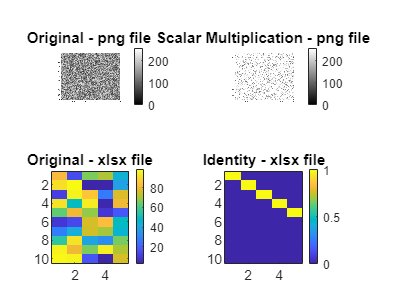

% Load .xlsx file
data_xlsx = readmatrix('random_data.xlsx', 'Sheet', 1);
% Scalar multiplication
new_data_xlsx = data_xlsx .* 3;
% Dot product
dot_prod_xlsx = dot(data_xlsx(:,1), data_xlsx(:,2));
% Triangle matrix
L_xlsx = tril(data_xlsx);
% Identity matrix
I_xlsx = eye(size(data_xlsx));

% Plot original file
subplot(223)
imagesc(data_xlsx)
title('Original - xlsx file')
colorbar
% Plot result file
subplot(224)
imagesc(I_xlsx)
title('Identity - xlsx file')
colorbar